# Equipollenza Polinomi

Nel seguente script la legge di controllo è ottenuta utilizzando il principio di equipollenza dei polinomi, in quanto, essendo il sistema del secondo ordine, è possibile caratterizzarne le performance in termini di $\zeta$, $\omega_n$. A differenza del LQR il vantaggio di questa metodologia è che permette di avere un maggiore controllo sulle performance dinamiche. Non a caso, l'LQR è sì un controllo ottimo, tuttavia, non si può specificare in maniera esplicita il tempo di assestamento, la sovraelongazione, ecc., ci si lascia dunque specificare le performance dalla minimizzazione di quella funzione quadratica, ed è per questo che alla fine è sempre opportuno andare a simulare il sistema per vedere se restituisce le caratteristiche di interesse.


$$\begin{cases}
\dot x_1 =x_2 \\
\dot{x_2} =- \frac{g}{l} \sin (x_1)- \frac{b}{ml^2}x_2+ \frac{u(t)}{ml^2}\\
y=x_1
\end{cases}$$


clear all, clc , close all
mkdir ('Risultati Equipollenza Polinomi')

syms x1 x2 u
    m = 1; 
    l = 1;
    b = 0.1;
    g = 9.81;
    r = pi;
    x_e=[pi,0];
% Definisci le equazioni del sistema
    x1_dot = x2;
    x2_dot = (-g/l)*sin(x1) - ((b*x2)/(m*l^2)) + (u/(m*l^2));

% Definisci il vettore di stato e il vettore di input
X = [x1; x2];
U = u;

% Calcola le matrici A, B, C e D
A = jacobian([x1_dot; x2_dot], X);
B = jacobian([x1_dot; x2_dot], U);

% Sostituisci i valori numerici delle costanti
A = subs(A, {g, l, b, m}, {9.81, 1, 0.1, 1});
B = subs(B, {g, l, b, m}, {9.81, 1, 0.1, 1});
% Visualizza le matrici A, B
disp('Matrice A:');

Matrice A:


disp(A); 

$$\left(\begin{array}{cc} 0 & 1\\ -\frac{981\,\cos\left(x_{1}\right)}{100} & -\frac{1}{10} \end{array}\right)$$

disp('Matrice B:');

Matrice B:


disp(B);

$$\left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

Nel caso in esame, dopo aver linearizzato intorno al punto di equilibrio instabile, le matrici diventano: 


$$A =\left(\begin{array}{cc} 0 & 1\\ 9.81 & -0.1 \end{array}\right)
\\ B=  \left(\begin{array}{cc} 0 \\ 1 \end{array}\right) \\
C=\left(\begin{array}{cc} 1 & 0 \end{array}\right)
$$


#### Analisi raggiungibilità(equivalente al caso precedente).

 A=[0 1;
    9.81 -1/10];
B=[0;1];
C=[1 0];
D=0;

Calcolo di $W_r$.

Wr = [B A*B];
% In alternativa anche con ctrb(A,B), comando che data la matrice A e B da
% direttamente la matrice di controllabilità
disp('Matrice Wr:');

Matrice Wr:


disp(Wr); 

         0    1.0000
    1.0000   -0.1000



rank(Wr);

## Equipollenza dei polinomi

Per evitare oscillazioni del sistema linearizzato è necessario che il polinomio caratteristico del sistema abbia radici reali. Per la stabilità c'è bisogno che tali radici siano a parte reale negativa e che siano assenti permutazioni di segno dunque $K_2 <0\ldotp 1$ e $K_{1\;} <-9\ldotp 81$. Si noti che con questo si evitano le oscilllazioni soltanto del sistema linearizzato, le performance reali devono infatti essere valutate sul sistema non lineare.

Imponendo a ciclo chiuso un tempo di salita pari a $T_r =0\ldotp 5s$, si ottiene:


$$T_r =\frac{2\ldotp 7}{\omega_0 }\leftrightarrow \omega_0 =\frac{2\ldotp 7}{T_r }=5\ldotp 4$$


Per avere un comportamento con una sovraelongazione che sia minore del $10%$ si impone:


$$\zeta =0\ldotp 9$$


Il polinomio caratteristico desiderato sarà quindi nella forma:


$$p\left(s\right)=s^2 +2\zeta \omega_0 s+\omega_0^2 =s^2 +9\ldotp 72s+29\ldotp 160$$


Per il calcolo del polinomio caratteristico viene usato il comando "charpoly" che consente di calcolare il polinomio caratteristico della matrice del sistema a ciclo chiuso.

syms K1 K2 
K_temp=[K1 K2]; 
pol = charpoly(A-B*K_temp) % det(sI-A+B*K)

$$pol = \left(\begin{array}{ccc} 1 & K_{2}+\frac{1}{10} & K_{1}-\frac{981}{100} \end{array}\right)$$

Si impone il tempo di salita pari a $T_r =0\ldotp 5$.

Tr = 0.5;
w0 = 2.7/Tr

w0 = 5.4000

zeta = 0.9

zeta = 0.9000

%calcoliamo i guadagni imponendo l'uguaglianza dei polinomi.
pol_d = [1 2*zeta*w0 w0^2]

pol_d =     1.0000    9.7200   29.1600


gains = solve(pol == pol_d, [K2, K1])

gains = struct with fields:
    K2: 481/50
    K1: 3897/100


K=[gains.K1 gains.K2]

$$K = \left(\begin{array}{cc} \frac{3897}{100} & \frac{481}{50} \end{array}\right)$$

K = double(subs(K, {K1, K2}, {gains.K1,gains.K2}));

Dal valore dei guadagni $K_1 =38\ldotp 97>9\ldotp 81,K_2 =9\ldotp 62>-0\ldotp 1$ si può osservare che le disuguaglianze sono verificate pertanto il polinomio è stabile. 

#### Simulazione e plot

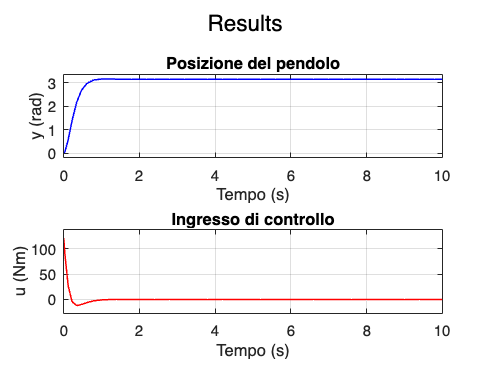

standard_model = 'WP2EquipollenzaPolinomi.slx';
open_system(standard_model);
data = sim(standard_model, 10);
plot_data(data, "WP2PolePlacement");
saveas(gcf, 'Risultati Equipollenza Polinomi/plot_result.png');

#### Analisi

results=stepinfo(data.y,data.t);
disp('Step Information for the Output');

Step Information for the Output


disp(results);

         RiseTime: 0.4684
    TransientTime: 0.7515
     SettlingTime: 0.7515
      SettlingMin: 2.9681
      SettlingMax: 3.1517
        Overshoot: 0.3206
       Undershoot: 0
             Peak: 3.1517
         PeakTime: 1.1942

